# EE175 Homework 6

clear
load("data.mat")
load("label.mat")

reshaped_imageTrain = reshape(imageTrain, 784, 5000) / 255;
reshaped_imageTest = reshape(imageTest, 784, 500) / 255;


## sample mean calculations (using class 5)

sample_meanTrain = sum(reshaped_imageTrain, 2) / 5000;
sample_indexClass = find(labelTrain == 5);
sample_meanClass = sum(reshaped_imageTrain(:, sample_indexClass), 2) / length(sample_indexClass);


## covariance calculations

covariance_train = reshaped_imageTrain - repmat(sample_meanTrain, 1, 5000);
covariance_train = covariance_train * transpose(covariance_train) ./ 5000;

covariance_class = reshaped_imageTrain(:, sample_indexClass) - repmat(sample_meanClass, 1, length(sample_indexClass));
covariance_class = covariance_class * transpose(covariance_class) ./ length(sample_indexClass);


## eigenvalue and eigenvector calculations

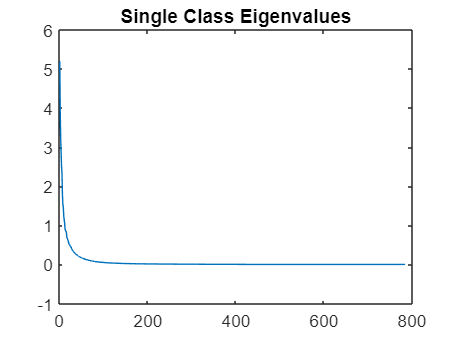

[eigen_vectorsTrain, eigen_valuesTrain] = eig(covariance_train);
sort_eigenTrain = sort(diag(eigen_valuesTrain), 'descend');
[~, eigen_indexTrain] = maxk(diag(eigen_valuesTrain), 10);

[eigen_vectorsClass, eigen_valuesClass] = eig(covariance_class);
sort_eigenClass = sort(diag(eigen_valuesClass), 'descend');
[~, eigen_indexClass] = maxk(diag(eigen_valuesClass), 10);

% display overall graphs
figure
title("Entire Dataset Eigenvalues");
plot(sort_eigenTrain);

%figure
title("Single Class Eigenvalues");

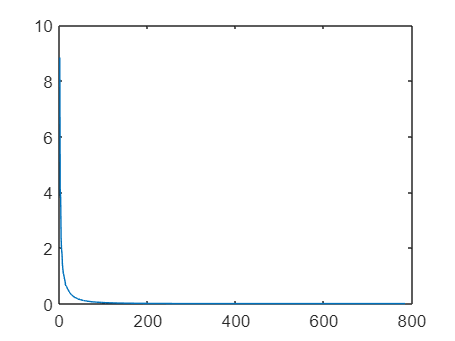

plot(sort_eigenClass);

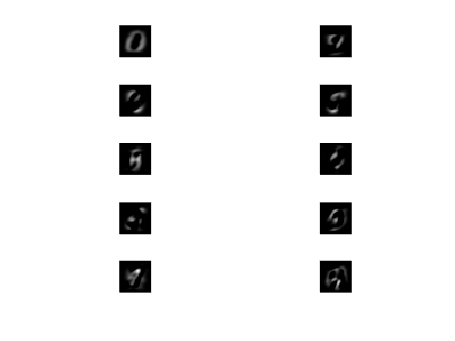


% plot principle components
figure
title("Entire Dataset Principle Features")
for i = 1:10
    subplot(5, 2, i);
    imshow(reshape(eigen_vectorsTrain(:, eigen_indexTrain(i)) * 5, 28, 28, 1));
end

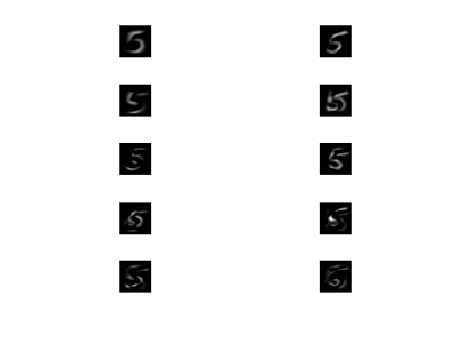


figure
title("Single Class Principle Features")
for i = 1:10
    subplot(5, 2, i);
    imshow(reshape(eigen_vectorsClass(:, eigen_indexClass(i)) * 5, 28, 28, 1));
end

## classify and Total Error Rate for Required Dimensions

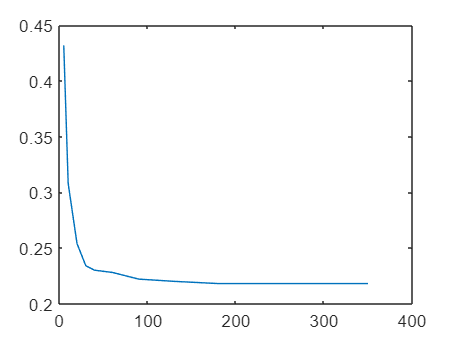

required_dimensions = [5, 10, 20, 30, 40, 60, 90, 130, 180, 250, 350];
total_error = zeros(1, length(required_dimensions));

% subtract sample mean from test sample
PCA_imageTest = reshaped_imageTest - repmat(sample_meanTrain, 1, 500);

for i = 1:length(required_dimensions)
    % grab top eigenvalue and eigenvector
    [~, eigen_indexTrain] = maxk(diag(eigen_valuesTrain), required_dimensions(i));
    chosen_eigenVectors = eigen_vectorsTrain(:, eigen_indexTrain);

    projected_imageTest = transpose(chosen_eigenVectors) * reshaped_imageTest; 
    projected_imageTrain = transpose(chosen_eigenVectors) * reshaped_imageTrain;

    % calculate trimmed sample mean for each class
    sample_means = zeros(required_dimensions(i), 10);
    logP = zeros(1, 10);
    for j = 1:10
        index = find(labelTrain == (j - 1));
        logP(j) = length(index);
        sample_means(:, j) = sum(projected_imageTrain(:, index), 2) ./ length(index);
    end
    
    % bayes decision rule
    predicted_labels = zeros(1, 500);
    logP = logP / 5000;
    for j = 1:500
        [~, class] = min(sum((repmat(projected_imageTest(:, j), 1, 10) - sample_means) .^  2) - 2 * log10(logP));
        predicted_labels(:, j) = class - 1;
    end

    % error function
    total_error(i) = length(nonzeros(labelTest - transpose(predicted_labels))) / 500;
end

figure
title("Error Across Subspaces");
plot(required_dimensions, total_error);

## image that is least like the digit 5

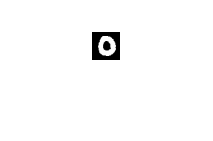

chosen_eigenVectors = eigen_vectorsClass(:, eigen_indexClass);
projected_imageTest = transpose(chosen_eigenVectors) * reshaped_imageTest; 
projected_imageTrain = transpose(chosen_eigenVectors) * reshaped_imageTrain;

index = find(labelTrain == 5);
sample_means = sum(projected_imageTrain(:, index), 2) ./ length(index);
[~, unique_index] = max(sum(projected_imageTest - repmat(sample_means, 1, 500)) .^ 2);

figure
imshow(reshape(reshaped_imageTest(:, unique_index), 28, 28, 1));